%% TEST SCRIPT for DroneInverseDynamicsStep

clear; clc;

% Parameters
m  = 1.5;        % mass [kg]
dt = 0.01;       % timestep [s]

% Initial state: [x y z vx vy vz]
s0 = [0 0 0 0 0 0];

% Input force
u_hover = [0 0 0];        % no force
u_push  = [100 100 100];        % force in x

### TEST 1: Dimension check

% DroneForwardDynamicsStep([0 0 0 0 0], u_push, m, dt)
% DroneForwardDynamicsStep(s0, [0 0], m, dt)
% DroneForwardDynamicsStep(s0, u_push, 0, dt)
% DroneForwardDynamicsStep(s0, u_push, dt, 0)

### TEST 2: Zero Input Behaviour

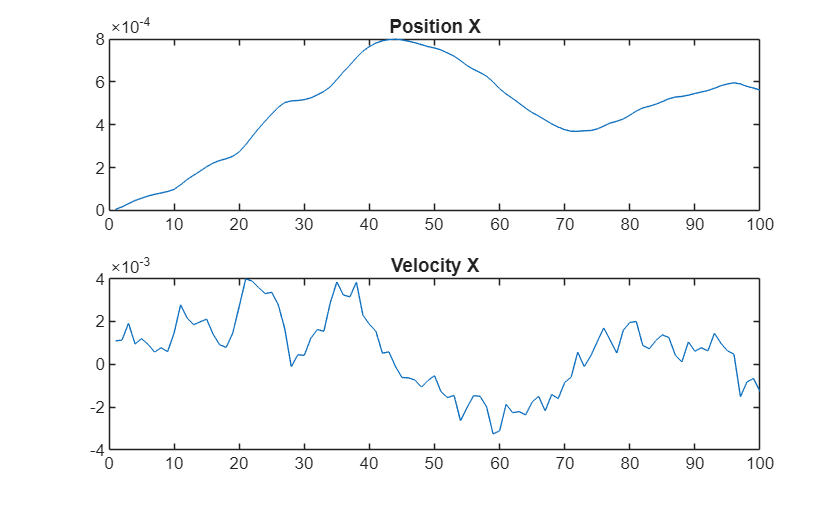

N = 100;
traj = zeros(N,6);
s = s0;

for k = 1:N
    s = DroneForwardDynamicsStep(s, u_hover, m, dt);
    traj(k,:) = s;
end

% Acceleration should be roughly zero, velocity and position should be roughly constant

figure;
subplot(2,1,1);
plot(traj(:,1)); title('Position X');
subplot(2,1,2);
plot(traj(:,4)); title('Velocity X');

### TEST 3: Constant Force Behaviour

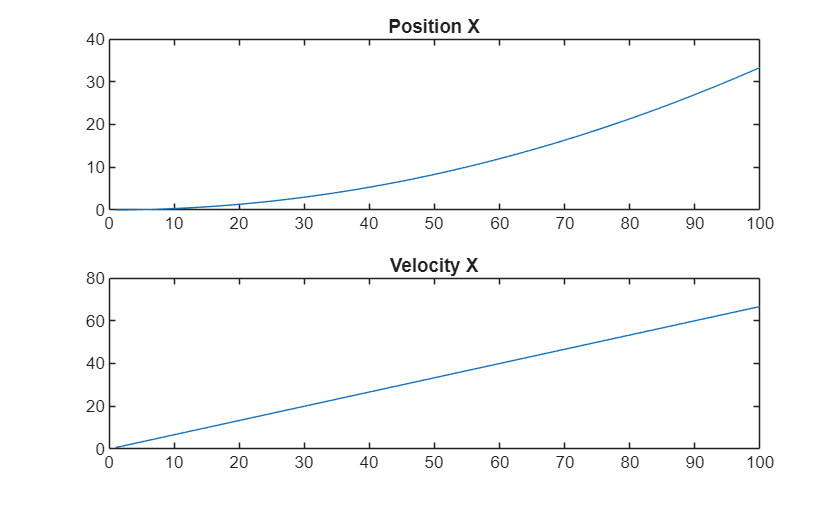


--- TEST 4: Large input warning ---


Check: should trigger warning



--- TEST 5: dt = 0 ---


Error: dt must be positive



--- TEST 6: Negative mass ---


Correctly caught error: Mass must be positive



--- TEST 7: Consistency check (finite difference) ---


Estimated acceleration: 66.7031      66.5798      56.8292


Expected acceleration:  66.6667      66.6667      66.6667


Check: should be close (noise aside)



--- ALL TESTS COMPLETED ---


N = 100;
traj = zeros(N,6);
s = s0;

for k = 1:N
    s = DroneForwardDynamicsStep(s, u_push, m, dt);
    traj(k,:) = s;
end

% Acceleration should be roughly zero, velocity and position should be roughly constant

figure;
subplot(2,1,1);
plot(traj(:,1)); title('Position X');
subplot(2,1,2);
plot(traj(:,4)); title('Velocity X');